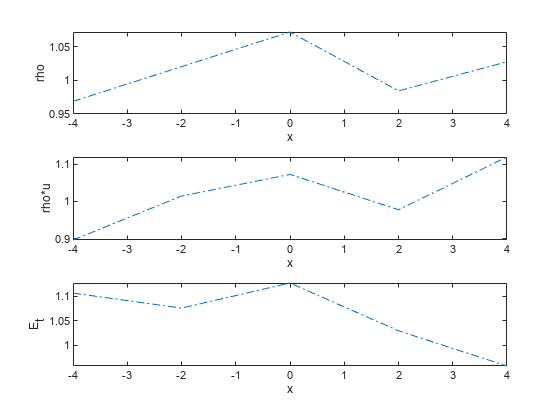

clear; close; clc;



% strecch goals:
% local time stepping
% use all 3 characteristics

% 3/11/2023 DEGUB NOTES:
% works with no sorouce terms blows up otherwise
% pressure goes complex cuaseing problems
% is suspect issue is with indexing

% define parameters

order = 1;
limiter = 0;
cfl = .25; % work out this
%steps = 2000
x_min = -4;
x_max = 4;
gamma = 1.4;
flow = 1; % defines problem 1 or 2


numCells = 100; % number of cells
%numCells = 5; % For Debug (this should work - it currently goes complex and should be hand calculable)
numFaces = numCells + 1; % number of faces

% solution arrays
Q_star = zeros(3,numCells);
Q = ones(3,numCells);


% boundary values (simple)
Q_inlet = zeros(3,1);
Q_outlet = zeros(3,1);


Initialize(flow);
Q_inlet = ExactSolu(x_min, flow);
Q_outlet = ExactSolu(x_max, flow);



% FOR DEBUG
Q_inlet = ExactSolu(x_max, flow);
Q_outlet = ExactSolu(x_min, flow);
% Q_inlet = [1; 1; 1];
% Q_outlet = [1; 1; 1];


% problem geometery
x_points = linspace(-4,4,numCells); % x locations

A = area(x_points); % area
dAdx = gradient(A,x_points); % derivative of area with respect to horizontal position

Delta_x = x_points(2) - x_points(1);

% create firue for plots
figure;


% setup for loop
res_initial = 1; % not ture but a guess to use for convergence (for now)

converged = false;

while converged == false

    %dt = %calculateTimeStep
    Delta_t = .001; % rough estimate for testing (100 200 400 steps will work)
    %TODO: compute timestepsize

    S = getSlope(Q, Q_inlet, Q_outlet, Delta_x, order);

    % SSP-RK2
    res_old = Residual(Q, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order);
    Q_star = Q + Delta_t * res_old; % intermediate step

    res_star = Residual(Q_star, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order);
    Q = .5 * (Q + Q_star + Delta_t * res_star); % final step

    % test convergence
    if abs(res_star) <= abs(res_initial * 1E-6)
        %break;
        converged = true;
    end

    plotState(x_points, Q);
    drawnow;
end


function res = Residual(Q, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order)
    S = getSlope(Q, Q_inlet, Q_outlet, Delta_x, order); % estimate the slope (recontrution)

    Q_triangle = Q - 1/2 * Delta_x * S; % value at left boundary of cv
    Q_square = Q + 1/2 * Delta_x * S; % value at right boundary of cv
    
    Q_triangle_ip1 = [Q_triangle(:,2:end), Q_outlet]; % value at left boundary of cv plus 1 index (Q_tirangle_i+1)
    Q_square_im1 = [Q_inlet, Q_square(:,1:end-1)]; % value at right boundary of cv minus 1 index (Q_square_i-1)


    % fluxes on contol volume baoundaries
    F_L = RienmannSolver(Q_triangle, Q_square_im1, gamma);
    F_R = RienmannSolver(Q_square, Q_triangle_ip1, gamma);

    % compute residual
    res = (F_L - F_R) ./ Delta_x + getSource(Q, gamma, A, dAdx);
    %res = (F_L - F_R) ./ Delta_x - getSource(Q, gamma, A, dAdx); % might fix blow up (worked for jackson)
end

function Flux = RienmannSolver(Q_L, Q_R, gamma)
    f_L = getFlux(Q_L, gamma);
    f_R = getFlux(Q_R, gamma);

    [u_L, ~, ~, ~, c_L] = getFlowProperties(Q_L, gamma);
    [u_R, ~, ~, ~, c_R] = getFlowProperties(Q_R, gamma);
    
    russanovFlux = abs((u_L + u_R) / 2 + (c_L + c_R) / 2) .* (Q_L - Q_R); % this should alsp work
    russanovFlux = (abs((u_L + u_R)) / 2 + (c_L + c_R) / 2) .* (Q_L - Q_R); % this is what it should be
    
    Flux = (f_L + f_R) / 2 - russanovFlux;
    %Flux = -(f_L + f_R) / 2 - russanovFlux;
end

function slope = getSlope(Q, Q_inlet, Q_outlet, Delta_x, order)
    if order == 2 % linear slope
        slope = ([Q(:,2:end), Q_outlet] - [Q_inlet, Q(:,1:end-1)]) / (2*Delta_x);
    elseif order == 1 % assume constnat
        slope = 0;
    else % we only support order 1 and 2 accuracy
        fprintf("Order %g not supported.", order);
    end
end


function [u, p, E, rho, c] = getFlowProperties(Q, gamma) % checked - not confident (ok?)
    % get thermodynamic properties of flow from state vector Q
    rho = Q(1,:);
    u = Q(2,:) ./ Q(1,:);
    p = (Q(3,:) - 1/2 .* Q(2,:).^2./Q(1,:)) * (gamma - 1); % currently p is going negative sometimes

    %p = abs(p); % For Debug

    % FOR DEBUG
    if sum(p < 0) > 0
        disp("negative p There is a bug")
    end

    E = Q(3);
    c = sqrt(gamma*p./rho); % given by josh sutton and jackson (this is correct)
    
    % FOR DEBUG
    if sum((gamma*p./rho) < 0) > 0
        disp("complex spd sound There is a bug")
    end
    %c = 1; % FOR DEBUG
end

function [G] = getSource(Q, gamma, A, dAdx) % checked
    [u, p, E, rho, ~] = getFlowProperties(Q, gamma);

    G = zeros([3,length(rho)]);
    G(1,:) = -rho .* u .* 1./A .* dAdx;
    G(2,:) = -rho .* u.^2 .* 1./A .* dAdx;
    G(3,:) = -u .* (E+p) .* 1./A .* dAdx;

    %G = zeros([3,length(rho)]); % FOR DEBUG
end

function [F] = getFlux(Q, gamma) % checked
    [u, p, E, rho, ~] = getFlowProperties(Q, gamma);
    
    F = zeros([3,length(rho)]);
    F(1,:) = rho .* u;
    F(2,:) = rho .* u.^2 + p;
    F(3,:) = u .* (E+p);
end

function plotState(x_points, Q)
    % Plot the conserved variables
    subplot(3,1,1);
    plot(x_points,Q(1,:),'-.');
    xlabel('x');
    ylabel('rho');
    %ylim([0.4,1.1]);
        
    subplot(3,1,2);
    plot(x_points,Q(2,:),'-.');
    xlabel('x');
    ylabel('rho*u');
    %ylim([-0.,0.8]);
    
    subplot(3,1,3);
    plot(x_points,Q(3,:),'-.');
    xlabel('x');
    ylabel('E_t');
    %ylim([0.8,2.0]);
end